## Problem 5

rng(0);

Generate a dataset comprising a set of $N$ real numbers drawn from the uniform distribution on $[0, 1]$. 

Consider various dataset sizes $N = 5, 10, 20, 40, 60, 80, 100, 500, 10^3 , 10^4$.

N=[5,10,20,40,60,80,100,500,10^3,10^4];

For each $N$, repeat the following experiment $M := 100$ times: 

- first, generate the data, 

- then, compute the average $\hat{\mu}$, and 

- finally, measure the error between the computed average $\hat{\mu}$ and the true mean $\mu$ as $\left| \hat{\mu} - \mu_{true}\right|$.

M=100;
m_true=0.5;

exp_data_1=[]; 

for n=N
    mu_v = zeros(100,1);
    for i=(1:100)
        mu_v(i) = abs(mean(rand(n,1)) - m_true);
    end
    exp_data_1 = [exp_data_1 mu_v];
end

    0.0001    0.0093    0.0824    0.0071    0.0105    0.0303    0.0033    0.0118    0.0026    0.0009
    0.0458    0.0466    0.0181    0.0573    0.0064    0.0126    0.0543    0.0143    0.0049    0.0023
    0.0797    0.1070    0.0023    0.0849    0.0369    0.0223    0.0071    0.0096    0.0141    0.0024
    0.0489    0.0067    0.0023    0.0182    0.0029    0.0089    0.0278    0.0038    0.0035    0.0005
    0.1751    0.0941    0.0103    0.0158    0.0453    0.0059    0.0112    0.0082    0.0159    0.0003
    0.1818    0.0342    0.0405    0.0232    0.0890    0.0017    0.0189    0.0215    0.0057    0.0026
    0.1212    0.1100    0.1153    0.0633    0.0257    0.0402    0.0090    0.0092    0.0047    0.0023
    0.0353    0.0055    0.0060    0.0143    0.0359    0.0077    0.0039    0.0063    0.0111    0.0036
    0.0383    0.1225    0.0747    0.0096    0.0602    0.0372    0.0533    0.0096    0.0063    0.0031
    0.0880    0.1469    0.0346    0.0414    0.0502    0.0099    0.0254    0.0042    0.0017 

disp(exp_data_1);

- For the uniform distribution, plot a single graph that shows the distribution of errors (across $M$ repeats) for all values of $N$ using a box-and-whisker plot. You may use the boxplot(.) function in Matlab. 

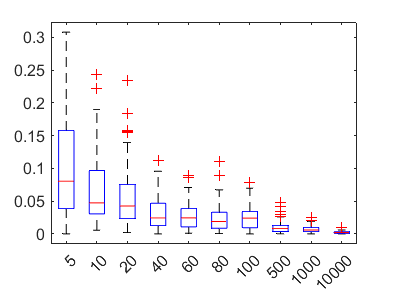

boxplot(exp_data_1,N);

-  Repeat the above question by replacing the uniform distribution by a Gaussian distribution with $\mu := 0$ and $\sigma^2 := 1$. 

mu=0;
sigma=1;
exp_data_2=[]; 

for n=N
    mu_v = zeros(100,1);
    for i=(1:100) %pls verify the syntax
        mu_v(i) = abs(mean(random('Normal',mu,sigma,n,1)) - mu);
    end
    exp_data_2 = [exp_data_2 mu_v];
end
disp(exp_data_2);

    0.8134    0.8334    0.4003    0.2415    0.1998    0.0901    0.1407    0.0109    0.0047    0.0023
    0.1617    0.5256    0.0323    0.0175    0.1064    0.0082    0.0583    0.0842    0.0067    0.0137
    0.0898    0.3231    0.0863    0.0001    0.0566    0.0233    0.0779    0.0336    0.0255    0.0135
    0.0521    0.0801    0.0335    0.2022    0.0407    0.1003    0.0335    0.0509    0.0328    0.0039
    0.1181    0.5617    0.3185    0.0198    0.0508    0.0627    0.0051    0.1065    0.0194    0.0038
    0.4234    0.1234    0.0452    0.1092    0.0997    0.0686    0.1959    0.0251    0.0090    0.0032
    0.0271    0.5232    0.1347    0.0034    0.0278    0.1973    0.0009    0.0739    0.0245    0.0084
    0.3675    0.0130    0.2928    0.0754    0.0228    0.0582    0.2356    0.0680    0.0371    0.0161
    0.8381    0.3882    0.1660    0.0008    0.0591    0.1932    0.0027    0.1687    0.0041    0.0165
    0.4144    0.0863    0.2348    0.1964    0.1843    0.1625    0.0271    0.0895    0.0139 

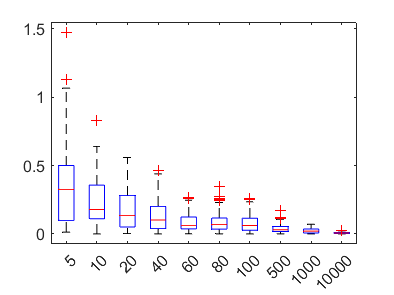


boxplot(exp_data_2,N);

-  Interpret what you see in the graphs. What happens to the distribution of error as $N$ increases ? 

errors going down wow